## Wighted Hinfnorm 

The H-inf norm is tested with the weighting function W_Delta

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


obtain controller gain K from Design procedure 2. 

param = control.DesignProcedure2(param,0,0);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0014    0.0014    0.0014    0.0082    0.1780    0.1794    0.1794    0.1820    3.0391    4.1899    4.2894    4.3188


Gamma is found to be:


ans = 1.0203

Eigenvalues of the decoupled systems are all negative 


ans =    -5.8861   -3.7193   -0.0473  -35.3607   -4.0279   -0.0231  -39.0341   -3.9902   -0.0230  -31.9229   -3.9896   -0.0225


Eigenvalues of the coupled systems are all negative 


ans =   -90.8194  -80.2837  -62.6284  -12.0194   -3.8636   -4.0289   -3.9907   -3.9912   -0.0473   -0.0225   -0.0231   -0.0230


## Non-wighted

param = model.calculateWDelta(param,1);
Mw = model.calculateMw(param);
fprintf("The largest singular value is: %.4f",max(max(sigma(Mw))))

The largest singular value is: 1.0118

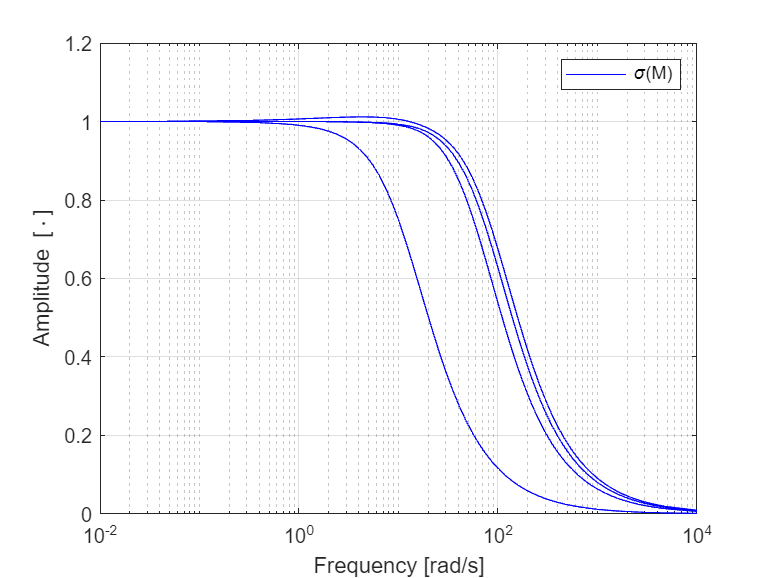

figure()
[sv, w] = sigma(Mw);
figure()
semilogx(w,sv,color=[0,0,1])
xlabel("Frequency [rad/s]")
ylabel("Amplitude [\cdot]")
legend('\sigma(M)')
xlim([10^-2,10^4])
grid on
saveas(gcf,"Images/SigamMNonWighted","epsc")

## Wighted

uses the filter specefied as:


$$\textbf{W}_{\Delta}(s) \overset{ss}{=} \left[ \begin{array}{c|c}
       \textbf{0}_4 & \textbf{0}_4 \\
      \hline
       \textbf{0}_{4} &  \left(\textbf{H}(\textbf{\xi}^*)+\mathbf{\mathcal{G}}\right)\left(\frac{\partial\textbf{g}(\mathbf{\omega}^*)}{\partial\mathbf{\omega}}-\bar{\mathbf{\Lambda}}^{-1}\right)
    \end{array}\right]
$$


param = model.calculateWDelta(param,0);
Mw = model.calculateMw(param); 

fprintf("The largest singular value is: %.4f",max(max(sigma(Mw))))

The largest singular value is: 0.2282

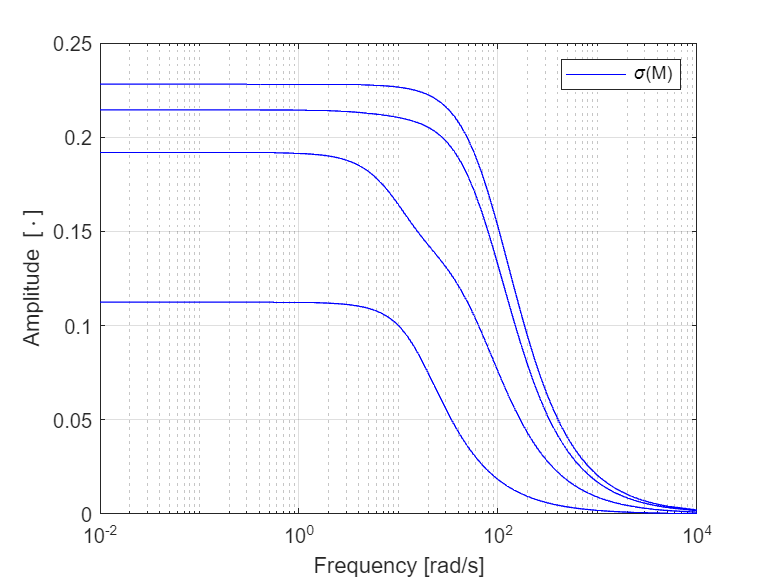

figure()
[sv, w] = sigma(Mw);
figure()
semilogx(w,sv,color=[0,0,1])
xlabel("Frequency [rad/s]")
ylabel("Amplitude [\cdot]")
legend('\sigma(M)')
xlim([10^-2,10^4])
grid on
saveas(gcf,"Images/SigamMWighted","epsc")